### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 


% Pick align_sec
% Pick align_sec
a1 = 0;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year4')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')

btl = readtable('Irminger_Sea-04_AR21_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07CTD1 = btl(btl.Cast == 7,:);
btlsum08CTD1 = btl(btl.Cast == 8,:);
btlsum10CTD1 = btl(btl.Cast == 10,:);
btlsum11CTD1 = btl(btl.Cast == 11,:);
btlsum12CTD1 = btl(btl.Cast == 12,:);

btlsum07CTD1 = combine_btl_files_woutCTDcal('AR21_007.csv',btlsum07CTD1);

btlsum08CTD1 = combine_btl_files_woutCTDcal('AR21_008.csv',btlsum08CTD1);

btlsum10CTD1 = combine_btl_files_woutCTDcal('AR21_010.csv',btlsum10CTD1);

btlsum11CTD1 = combine_btl_files_woutCTDcal('AR21_011.csv',btlsum11CTD1);

btlsum12CTD1 = combine_btl_files_woutCTDcal('AR21_012.csv',btlsum12CTD1);


btlsum07CTD2 = btl(btl.Cast == 7,:);
btlsum08CTD2 = btl(btl.Cast == 8,:);
btlsum10CTD2 = btl(btl.Cast == 10,:);
btlsum11CTD2 = btl(btl.Cast == 11,:);
btlsum12CTD2 = btl(btl.Cast == 12,:);

btlsum07CTD2 = combine_btl_files_woutCTDcal('AR21_007.csv',btlsum07CTD2);

btlsum08CTD2 = combine_btl_files_woutCTDcal('AR21_008.csv',btlsum08CTD2);

btlsum10CTD2 = combine_btl_files_woutCTDcal('AR21_010.csv',btlsum10CTD2);

btlsum11CTD2 = combine_btl_files_woutCTDcal('AR21_011.csv',btlsum11CTD2);

btlsum12CTD2 = combine_btl_files_woutCTDcal('AR21_012.csv',btlsum12CTD2);


btlsum_yr4 = [btlsum07CTD1; btlsum08CTD1; btlsum10CTD1; btlsum11CTD1; btlsum12CTD1];
btlsum0 = [btlsum10CTD1; btlsum11CTD1; btlsum12CTD1]; %%

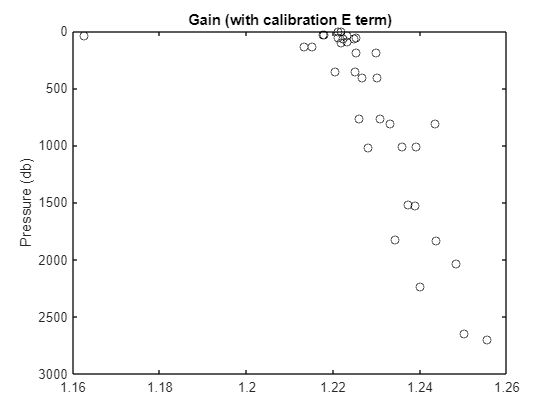

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same oxgen sensor whole cruise  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.61240e-001);
cal.VOFFSET = double(-5.10000e-001);
cal.A = double(-5.44340e-003);
cal.B = double(3.01750e-004);
cal.C = double(-4.29640e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.04000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0930';
cal.OCALDATE = '11-Nov-16';

H = [-0.033, 5000, 1450]; % Default 

cal1 = cal;
cal2 = cal; 

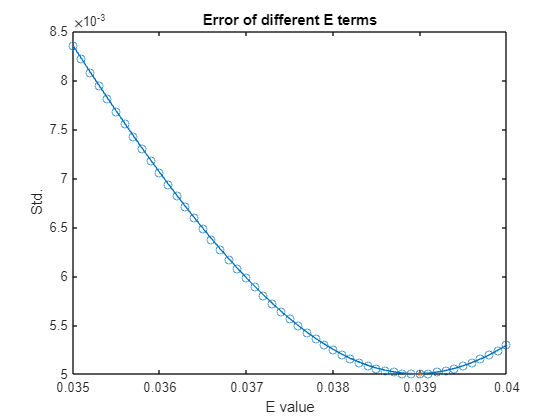

cal.E2 = 0.039


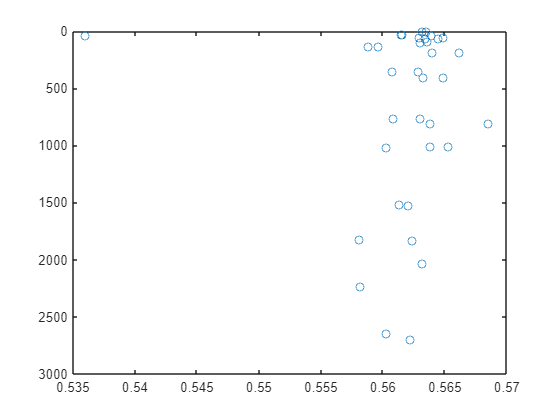

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal1] = E2_calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with outlier removed

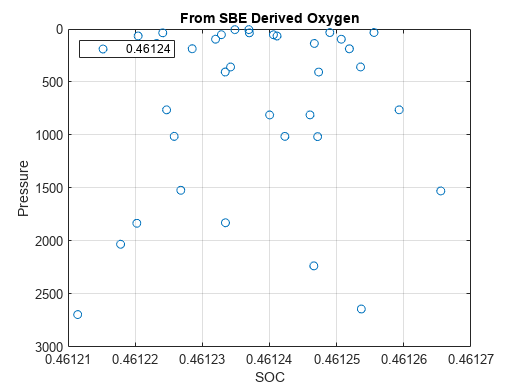

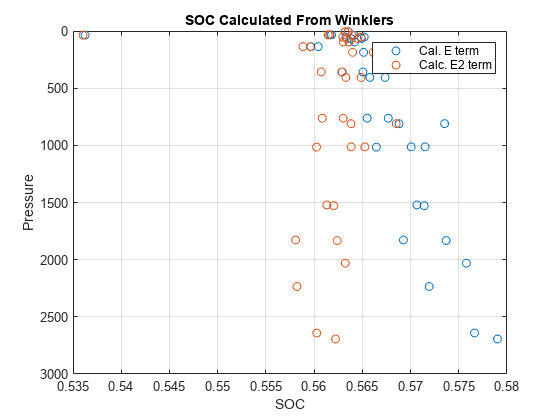

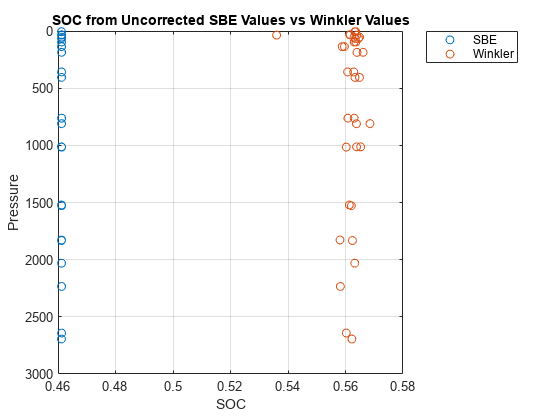

New SOC = 0.56188
EGain = 1.2182+/- 0.010849



[cal1] = Gain_E2_Calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with any outliers removed

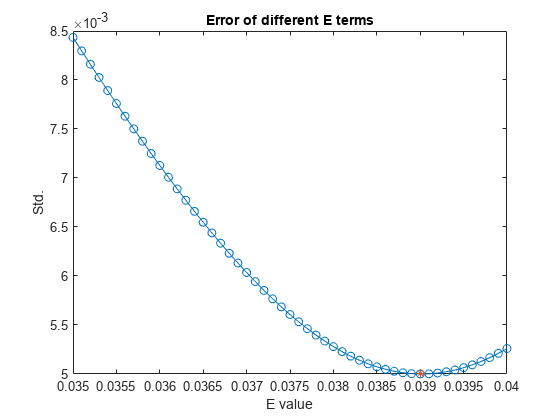

cal.E2 = 0.039


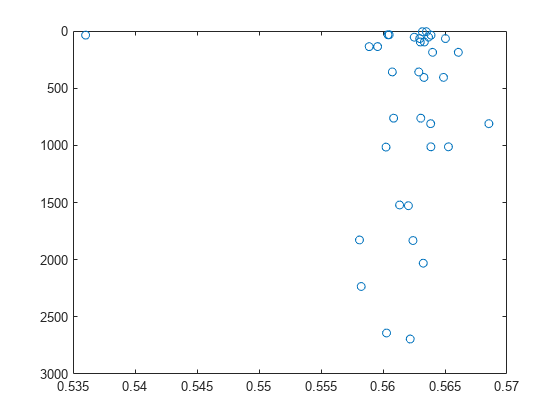


[cal2] = E2_calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with outlier removed

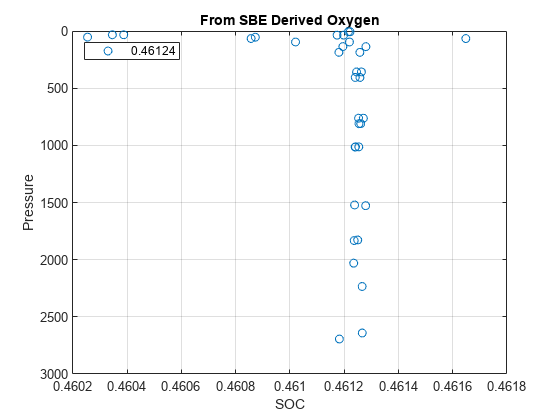

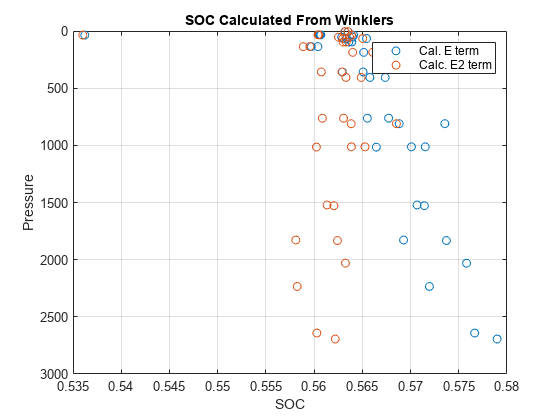

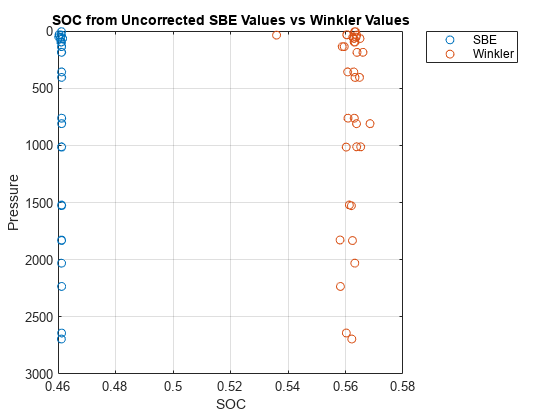

New SOC = 0.56177
EGain = 1.218+/- 0.010841



[cal2] = Gain_E2_Calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 8 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
cast01uCTD1 = readSBScnv( 'uAR21_001.cnv' );
cast02uCTD1 = readSBScnv( 'uAR21_002.cnv' );
cast03uCTD1 = readSBScnv( 'uAR21_003.cnv' );
cast04uCTD1 = readSBScnv( 'uAR21_004.cnv' );
cast05uCTD1 = readSBScnv( 'uAR21_005.cnv' );
cast06uCTD1 = readSBScnv( 'uAR21_006.cnv' );
cast07uCTD1 = readSBScnv( 'uAR21_007.cnv' );
cast08uCTD1 = readSBScnv( 'uAR21_008.cnv' );
cast09uCTD1 = readSBScnv( 'uAR21_009.cnv' );
cast10uCTD1 = readSBScnv( 'uAR21_010.cnv' );
cast11uCTD1 = readSBScnv( 'uAR21_011.cnv' );
cast12uCTD1 = readSBScnv( 'uAR21_012.cnv' );

cast01dCTD1 = readSBScnv( 'dAR21_001.cnv' );
cast02dCTD1 = readSBScnv( 'dAR21_002.cnv' );
cast03dCTD1 = readSBScnv( 'dAR21_003.cnv' );
cast04dCTD1 = readSBScnv( 'dAR21_004.cnv' );
cast05dCTD1 = readSBScnv( 'dAR21_005.cnv' );
cast06dCTD1 = readSBScnv( 'dAR21_006.cnv' );
cast07dCTD1 = readSBScnv( 'dAR21_007.cnv' );
cast08dCTD1 = readSBScnv( 'dAR21_008.cnv' );
cast09dCTD1 = readSBScnv( 'dAR21_009.cnv' );
cast10dCTD1 = readSBScnv( 'dAR21_010.cnv' );
cast11dCTD1 = readSBScnv( 'dAR21_011.cnv' );
cast12dCTD1 = readSBScnv( 'dAR21_012.cnv' );

cast01uCTD2 = readSBScnv( 'uAR21_001.cnv' );
cast02uCTD2 = readSBScnv( 'uAR21_002.cnv' );
cast03uCTD2 = readSBScnv( 'uAR21_003.cnv' );
cast04uCTD2 = readSBScnv( 'uAR21_004.cnv' );
cast05uCTD2 = readSBScnv( 'uAR21_005.cnv' );
cast06uCTD2 = readSBScnv( 'uAR21_006.cnv' );
cast07uCTD2 = readSBScnv( 'uAR21_007.cnv' );
cast08uCTD2 = readSBScnv( 'uAR21_008.cnv' );
cast09uCTD2 = readSBScnv( 'uAR21_009.cnv' );
cast10uCTD2 = readSBScnv( 'uAR21_010.cnv' );
cast11uCTD2 = readSBScnv( 'uAR21_011.cnv' );
cast12uCTD2 = readSBScnv( 'uAR21_012.cnv' );

cast01dCTD2 = readSBScnv( 'dAR21_001.cnv' );
cast02dCTD2 = readSBScnv( 'dAR21_002.cnv' );
cast03dCTD2 = readSBScnv( 'dAR21_003.cnv' );
cast04dCTD2 = readSBScnv( 'dAR21_004.cnv' );
cast05dCTD2 = readSBScnv( 'dAR21_005.cnv' );
cast06dCTD2 = readSBScnv( 'dAR21_006.cnv' );
cast07dCTD2 = readSBScnv( 'dAR21_007.cnv' );
cast08dCTD2 = readSBScnv( 'dAR21_008.cnv' );
cast09dCTD2 = readSBScnv( 'dAR21_009.cnv' );
cast10dCTD2 = readSBScnv( 'dAR21_010.cnv' );
cast11dCTD2 = readSBScnv( 'dAR21_011.cnv' );
cast12dCTD2 = readSBScnv( 'dAR21_012.cnv' );

% Format to table without Leah's product 
[cast01uCTD1, ~] = combine_CTD_files_woutCTDcal(cast01uCTD1); [cast01dCTD1, ~] = combine_CTD_files_woutCTDcal(cast01dCTD1);  
[cast02uCTD1, ~] = combine_CTD_files_woutCTDcal(cast02uCTD1); [cast02dCTD1, ~] = combine_CTD_files_woutCTDcal(cast02dCTD1);  
[cast03uCTD1, ~] = combine_CTD_files_woutCTDcal(cast03uCTD1); [cast03dCTD1, ~] = combine_CTD_files_woutCTDcal(cast03dCTD1);  
[cast04uCTD1, ~] = combine_CTD_files_woutCTDcal(cast04uCTD1); [cast04dCTD1, ~] = combine_CTD_files_woutCTDcal(cast04dCTD1);  
[cast05uCTD1, ~] = combine_CTD_files_woutCTDcal(cast05uCTD1); [cast05dCTD1, ~] = combine_CTD_files_woutCTDcal(cast05dCTD1);  
[cast06uCTD1, ~] = combine_CTD_files_woutCTDcal(cast06uCTD1); [cast06dCTD1, ~] = combine_CTD_files_woutCTDcal(cast06dCTD1);  
[cast07uCTD1, ~] = combine_CTD_files_woutCTDcal(cast07uCTD1); [cast07dCTD1, ~] = combine_CTD_files_woutCTDcal(cast07dCTD1);  
[cast08uCTD1, ~] = combine_CTD_files_woutCTDcal(cast08uCTD1); [cast08dCTD1, ~] = combine_CTD_files_woutCTDcal(cast08dCTD1);  
[cast09uCTD1, ~] = combine_CTD_files_woutCTDcal(cast09uCTD1); [cast09dCTD1, ~] = combine_CTD_files_woutCTDcal(cast09dCTD1);  
[cast10uCTD1, ~] = combine_CTD_files_woutCTDcal(cast10uCTD1); [cast10dCTD1, ~] = combine_CTD_files_woutCTDcal(cast10dCTD1); 
[cast11uCTD1, ~] = combine_CTD_files_woutCTDcal(cast11uCTD1); [cast11dCTD1, ~] = combine_CTD_files_woutCTDcal(cast11dCTD1); 
[cast12uCTD1, ~] = combine_CTD_files_woutCTDcal(cast12uCTD1); [cast12dCTD1, ~] = combine_CTD_files_woutCTDcal(cast12dCTD1); 

[cast01uCTD2, ~] = combine_CTD_files_woutCTDcal(cast01uCTD2); [cast01dCTD2, ~] = combine_CTD_files_woutCTDcal(cast01dCTD2);  
[cast02uCTD2, ~] = combine_CTD_files_woutCTDcal(cast02uCTD2); [cast02dCTD2, ~] = combine_CTD_files_woutCTDcal(cast02dCTD2);  
[cast03uCTD2, ~] = combine_CTD_files_woutCTDcal(cast03uCTD2); [cast03dCTD2, ~] = combine_CTD_files_woutCTDcal(cast03dCTD2);  
[cast04uCTD2, ~] = combine_CTD_files_woutCTDcal(cast04uCTD2); [cast04dCTD2, ~] = combine_CTD_files_woutCTDcal(cast04dCTD2);  
[cast05uCTD2, ~] = combine_CTD_files_woutCTDcal(cast05uCTD2); [cast05dCTD2, ~] = combine_CTD_files_woutCTDcal(cast05dCTD2);  
[cast06uCTD2, ~] = combine_CTD_files_woutCTDcal(cast06uCTD2); [cast06dCTD2, ~] = combine_CTD_files_woutCTDcal(cast06dCTD2);  
[cast07uCTD2, ~] = combine_CTD_files_woutCTDcal(cast07uCTD2); [cast07dCTD2, ~] = combine_CTD_files_woutCTDcal(cast07dCTD2);  
[cast08uCTD2, ~] = combine_CTD_files_woutCTDcal(cast08uCTD2); [cast08dCTD2, ~] = combine_CTD_files_woutCTDcal(cast08dCTD2);  
[cast09uCTD2, ~] = combine_CTD_files_woutCTDcal(cast09uCTD2); [cast09dCTD2, ~] = combine_CTD_files_woutCTDcal(cast09dCTD2);  
[cast10uCTD2, ~] = combine_CTD_files_woutCTDcal(cast10uCTD2); [cast10dCTD2, ~] = combine_CTD_files_woutCTDcal(cast10dCTD2); 
[cast11uCTD2, ~] = combine_CTD_files_woutCTDcal(cast11uCTD2); [cast11dCTD2, ~] = combine_CTD_files_woutCTDcal(cast11dCTD2); 
[cast12uCTD2, ~] = combine_CTD_files_woutCTDcal(cast12uCTD2); [cast12dCTD2, ~] = combine_CTD_files_woutCTDcal(cast12dCTD2); 


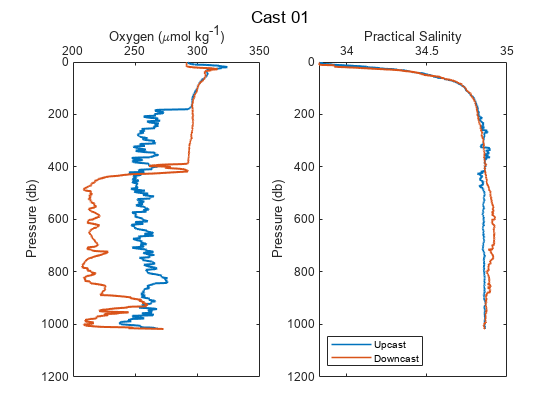

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_woutCTDcal(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast01uCTD1, cast01dCTD1, btlsum01CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast01uCTD1,cast01dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 01');

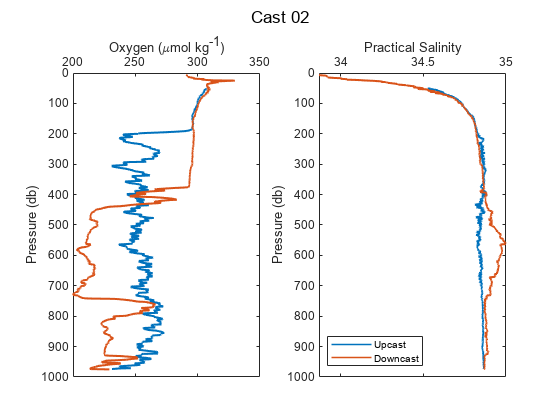

[cast02uCTD1, cast02dCTD1, btlsum02CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD1,cast02dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 02');

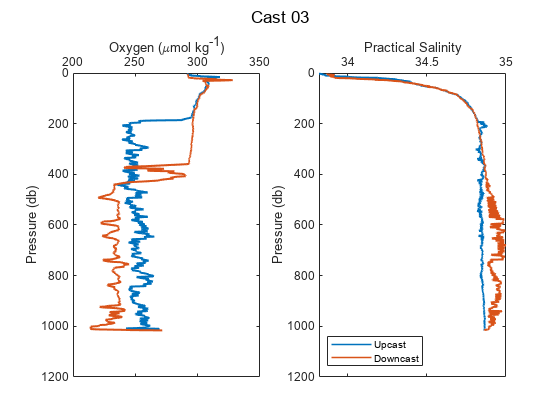

[cast03uCTD1, cast03dCTD1, btlsum03CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD1,cast03dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 03');

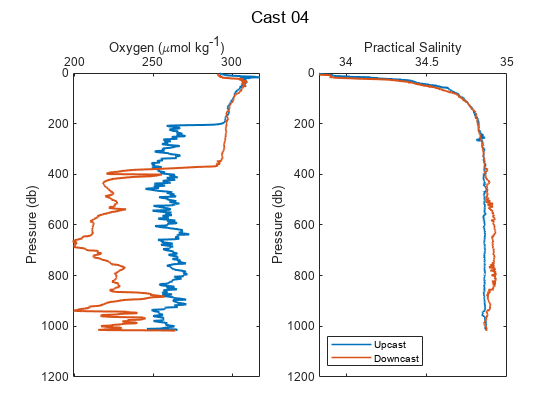

[cast04uCTD1, cast04dCTD1, btlsum04CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD1,cast04dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 04');

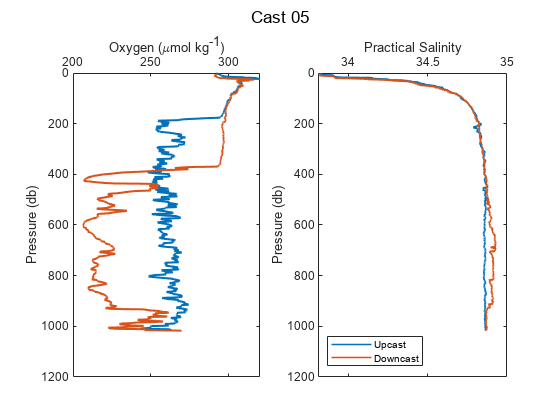

[cast05uCTD1, cast05dCTD1, btlsum05CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD1,cast05dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 05');

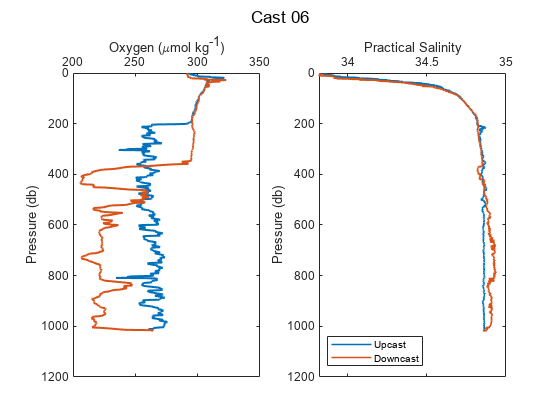

[cast06uCTD1, cast06dCTD1, btlsum06CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD1,cast06dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 06');

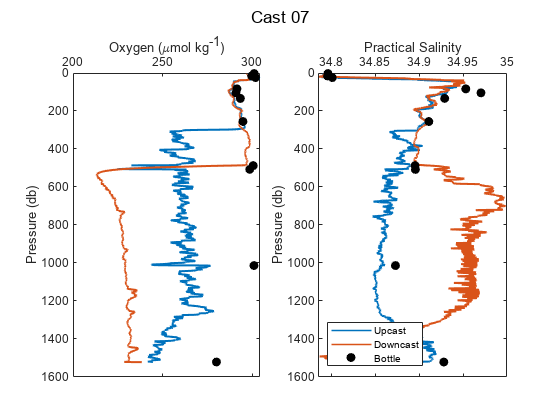

[cast07uCTD1, cast07dCTD1, btlsum07CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD1,cast07dCTD1,cal1,btlsum07CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 07');

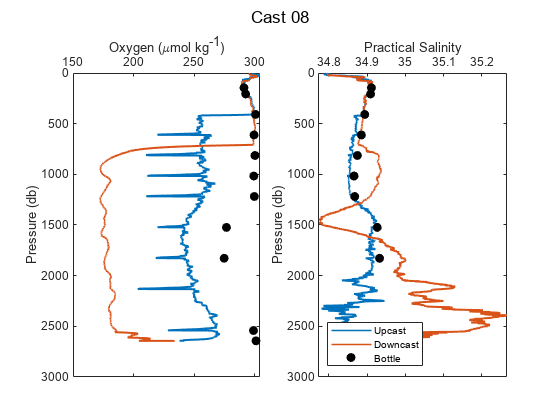

[cast08uCTD1, cast08dCTD1, btlsum08CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD1,cast08dCTD1,cal1,btlsum08CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 08');

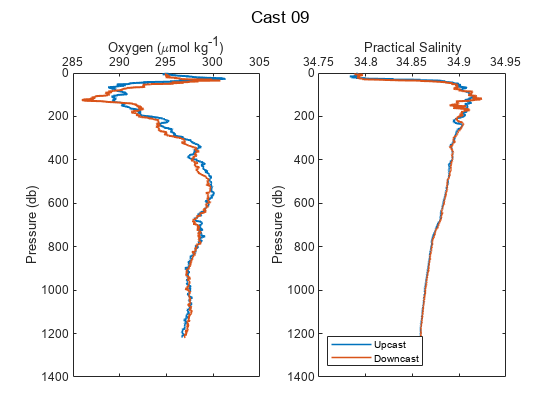

[cast09uCTD1, cast09dCTD1, btlsum09CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD1,cast09dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 09');

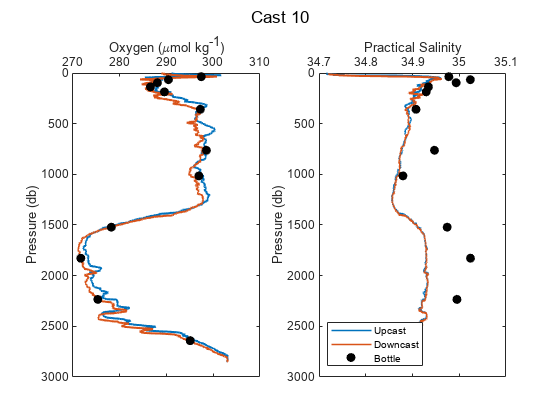

[cast10uCTD1, cast10dCTD1, btlsum10CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast10uCTD1,cast10dCTD1,cal1,btlsum10CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 10');

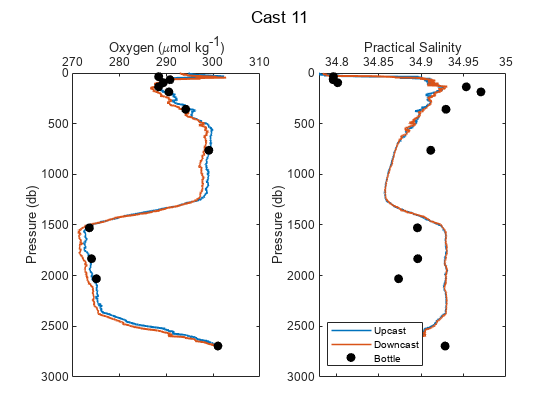

[cast11uCTD1, cast11dCTD1, btlsum11CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast11uCTD1,cast11dCTD1,cal1,btlsum11CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 11');

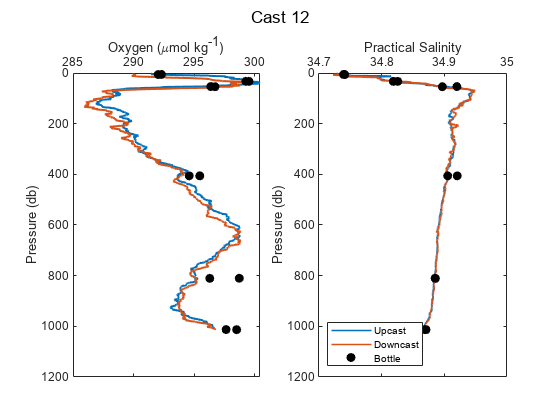

[cast12uCTD1, cast12dCTD1, btlsum12CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast12uCTD1,cast12dCTD1,cal1,btlsum12CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 12');

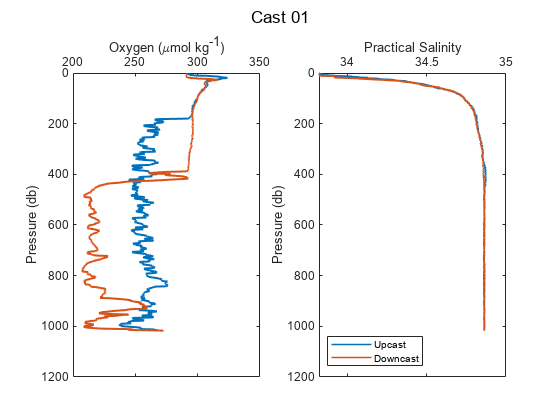


[cast01uCTD2, cast01dCTD2, btlsum01CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast01uCTD2,cast01dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 01');

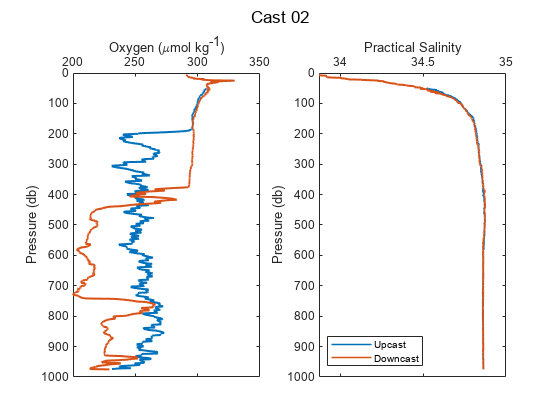

[cast02uCTD2, cast02dCTD2, btlsum02CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD2,cast02dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 02');

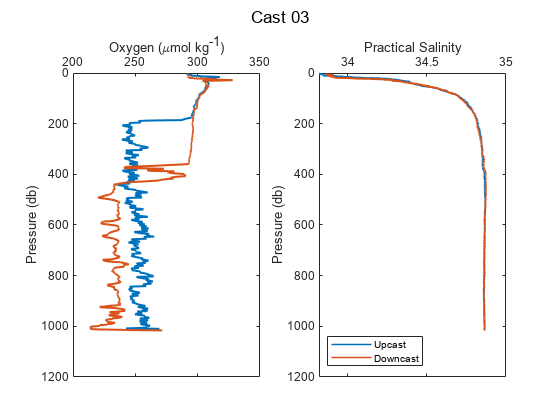

[cast03uCTD2, cast03dCTD2, btlsum03CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD2,cast03dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 03');

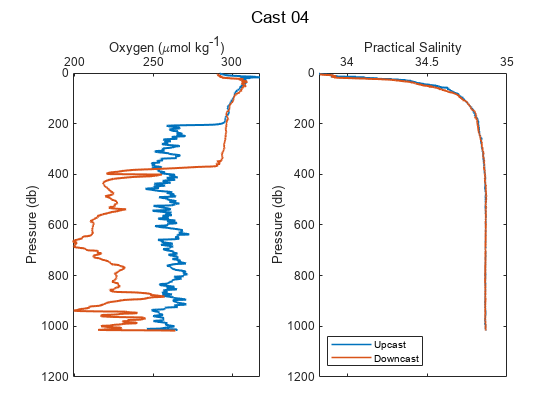

[cast04uCTD2, cast04dCTD2, btlsum04CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD2,cast04dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 04');

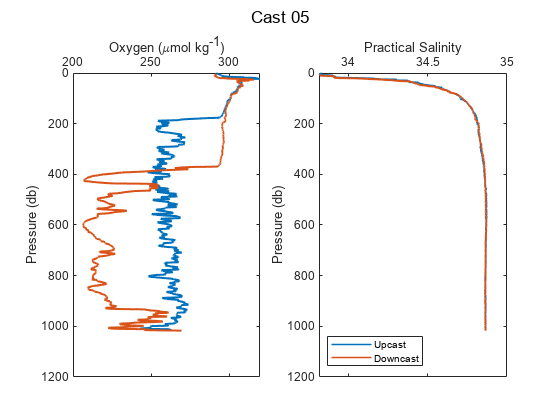

[cast05uCTD2, cast05dCTD2, btlsum05CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD2,cast05dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 05');

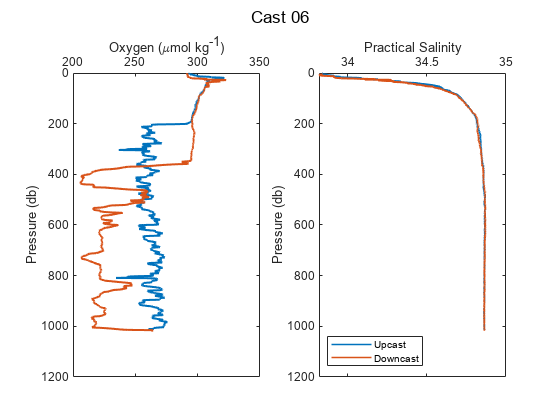

[cast06uCTD2, cast06dCTD2, btlsum06CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD2,cast06dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 06');

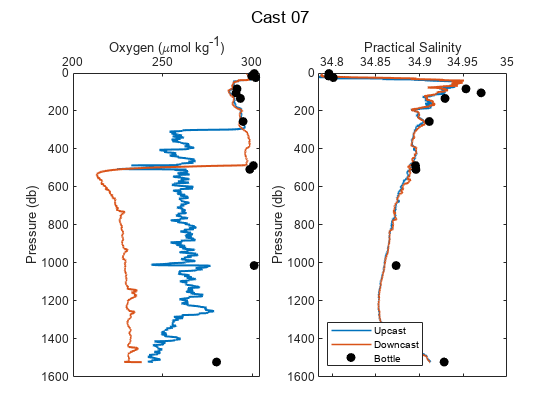

[cast07uCTD2, cast07dCTD2, btlsum07CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD2,cast07dCTD2,cal2,btlsum07CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 07');

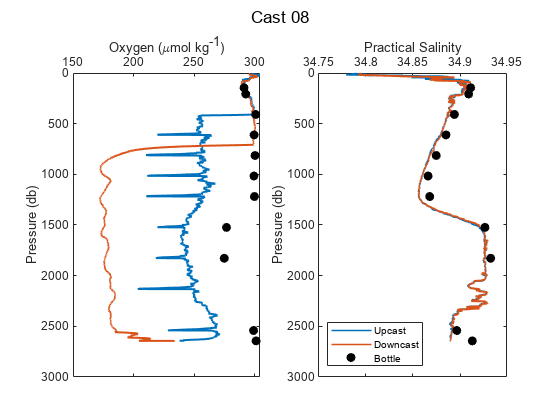

[cast08uCTD2, cast08dCTD2, btlsum08CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD2,cast08dCTD2,cal2,btlsum08CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 08');

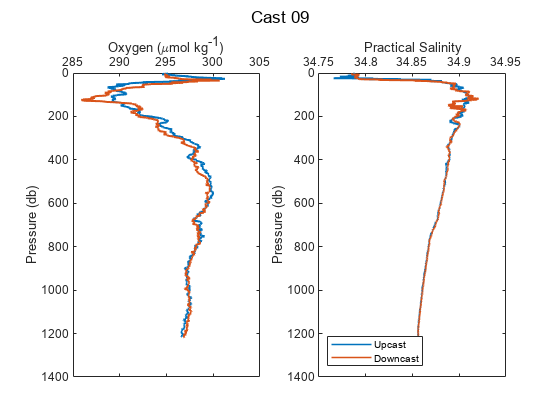

[cast09uCTD2, cast09dCTD2, btlsum09CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD2,cast09dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 09');

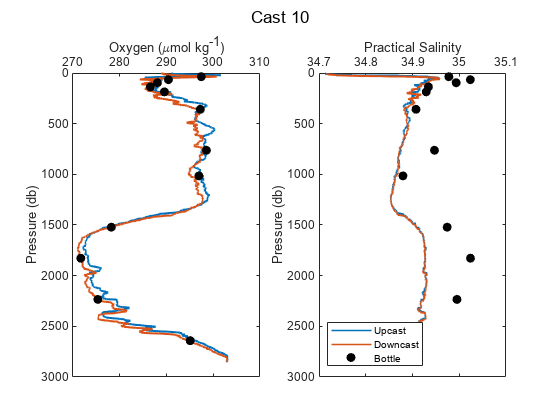

[cast10uCTD2, cast10dCTD2, btlsum10CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast10uCTD2,cast10dCTD2,cal2,btlsum10CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 10');

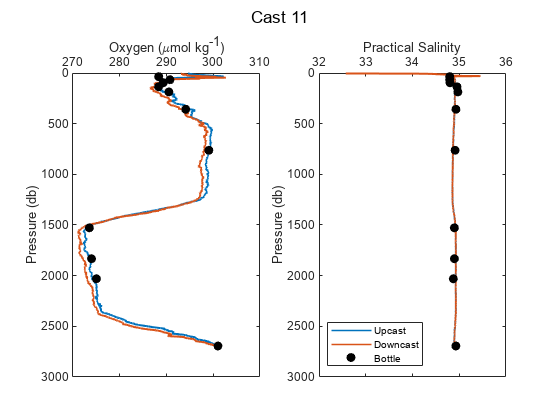

[cast11uCTD2, cast11dCTD2, btlsum11CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast11uCTD2,cast11dCTD2,cal2,btlsum11CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 11');

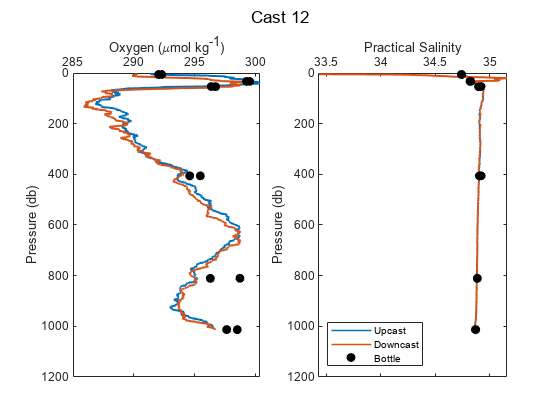

[cast12uCTD2, cast12dCTD2, btlsum12CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast12uCTD2,cast12dCTD2,cal2,btlsum12CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 12');

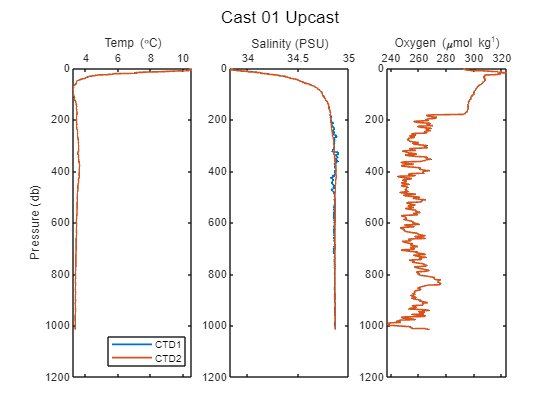

DO1 - DO2 = 0.054485 +/- 0.0037795 umol/kg


[DOdiff01u, DOstd01] = CTD1vsCTD2(cast01uCTD1,cast01uCTD2,btlsum01CTD1,'Cast 01 Upcast');

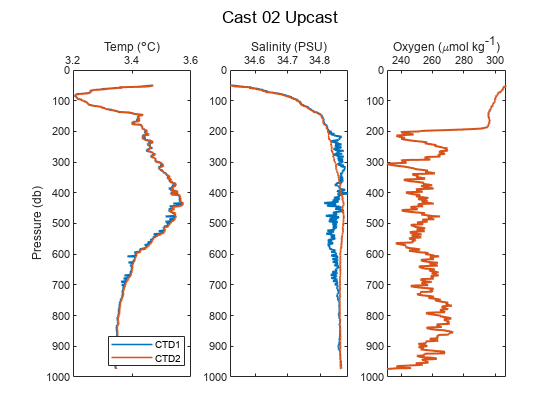

DO1 - DO2 = 0.054116 +/- 0.0042495 umol/kg


[DOdiff02u, DOstd02] = CTD1vsCTD2(cast02uCTD1,cast02uCTD2,btlsum02CTD1,'Cast 02 Upcast');

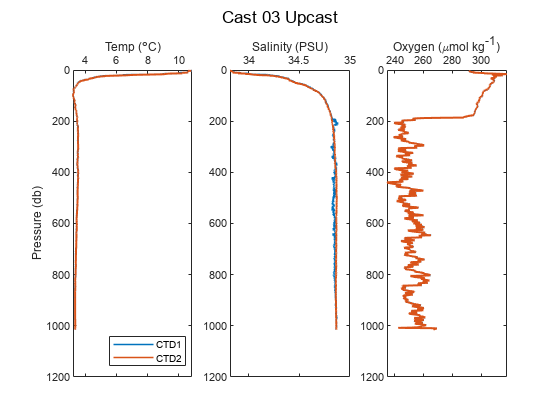

DO1 - DO2 = 0.05431 +/- 0.0039832 umol/kg


[DOdiff03u, DOstd03] = CTD1vsCTD2(cast03uCTD1,cast03uCTD2,btlsum03CTD1,'Cast 03 Upcast');

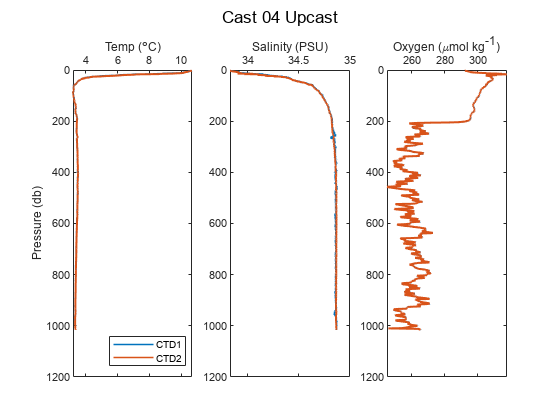

DO1 - DO2 = 0.05456 +/- 0.0034222 umol/kg


[DOdiff04u, DOstd04] = CTD1vsCTD2(cast04uCTD1,cast04uCTD2,btlsum04CTD1,'Cast 04 Upcast');

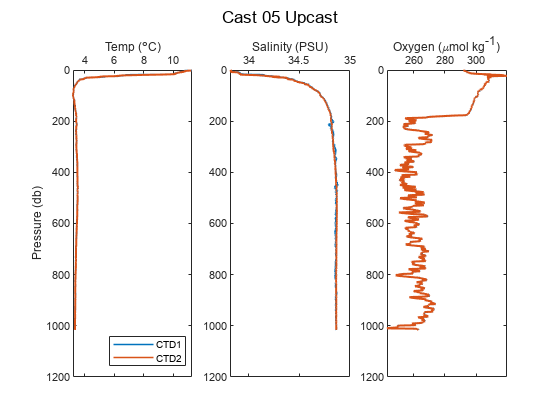

DO1 - DO2 = 0.054592 +/- 0.0034218 umol/kg


[DOdiff05u, DOstd05] = CTD1vsCTD2(cast05uCTD1,cast05uCTD2,btlsum05CTD1,'Cast 05 Upcast');

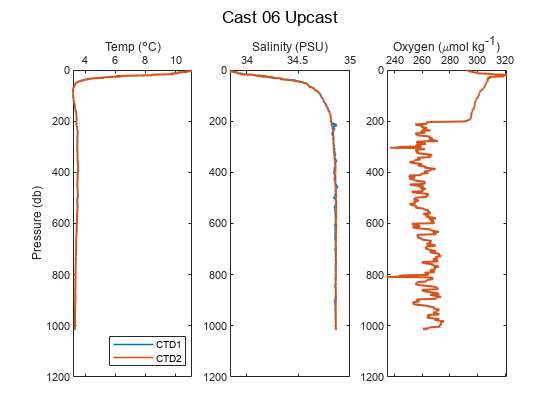

DO1 - DO2 = 0.055032 +/- 0.0033162 umol/kg


[DOdiff06u, DOstd06] = CTD1vsCTD2(cast06uCTD1,cast06uCTD2,btlsum06CTD1,'Cast 06 Upcast');

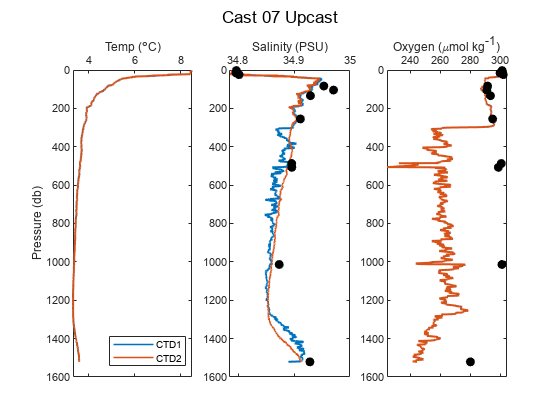

DO1 - DO2 = 0.054509 +/- 0.0036147 umol/kg


[DOdiff07u, DOstd07] = CTD1vsCTD2(cast07uCTD1,cast07uCTD2,btlsum07CTD1,'Cast 07 Upcast');

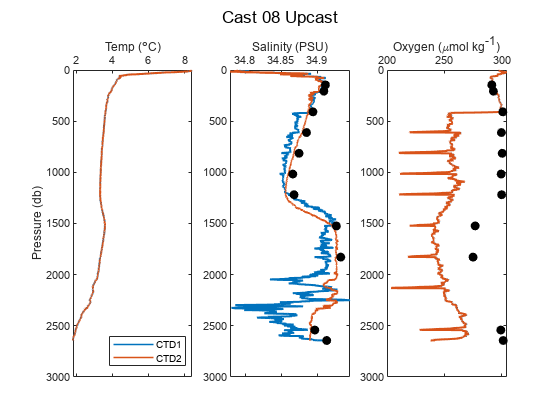

DO1 - DO2 = 0.055059 +/- 0.0055266 umol/kg


[DOdiff08u, DOstd08] = CTD1vsCTD2(cast08uCTD1,cast08uCTD2,btlsum08CTD1,'Cast 08 Upcast');

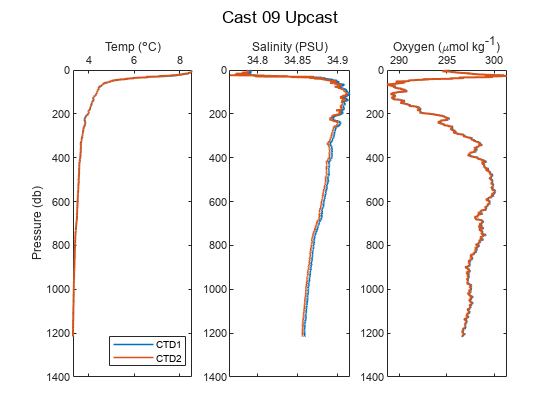

DO1 - DO2 = 0.059654 +/- 0.00069366 umol/kg


[DOdiff09u, DOstd09] = CTD1vsCTD2(cast09uCTD1,cast09uCTD2,btlsum09CTD1,'Cast 09 Upcast');

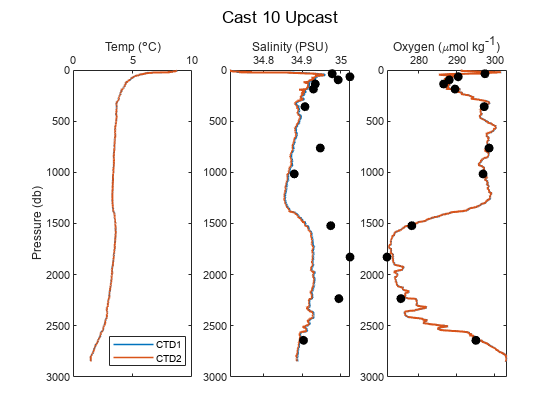

DO1 - DO2 = 0.058093 +/- 0.0020813 umol/kg


[DOdiff10u, DOstd10] = CTD1vsCTD2(cast10uCTD1,cast10uCTD2,btlsum10CTD1,'Cast 10 Upcast');

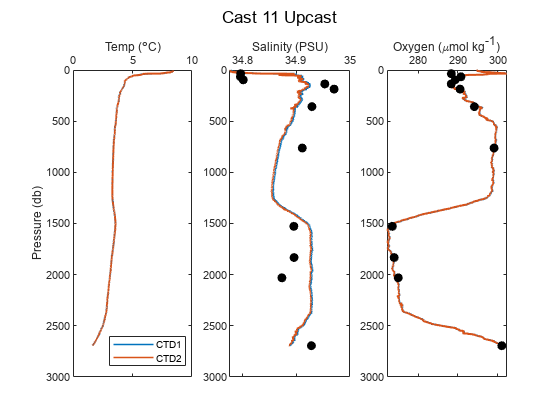

DO1 - DO2 = 0.057849 +/- 0.0021495 umol/kg


[DOdiff11u, DOstd11] = CTD1vsCTD2(cast11uCTD1,cast11uCTD2,btlsum11CTD1,'Cast 11 Upcast');

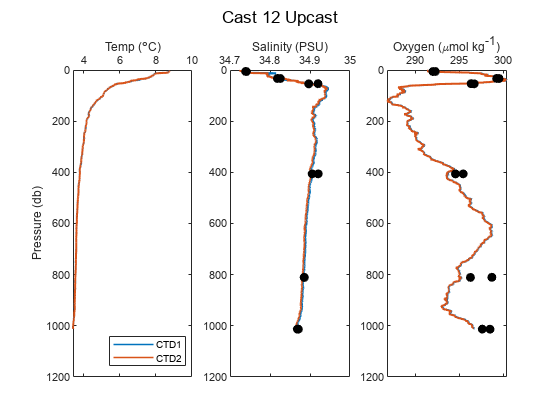

DO1 - DO2 = 0.059036 +/- 0.000809 umol/kg


[DOdiff12u, DOstd12] = CTD1vsCTD2(cast12uCTD1,cast12uCTD2,btlsum12CTD1,'Cast 12 Upcast');

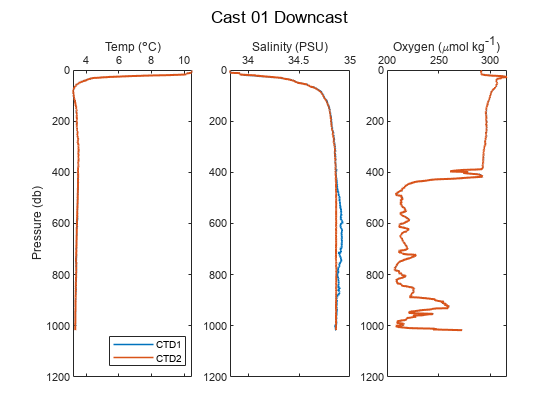

DO1 - DO2 = 0.048178 +/- 0.010404 umol/kg



[DOdiff01d, DOstd01] = CTD1vsCTD2(cast01dCTD1,cast01dCTD2,btlsum01CTD1,'Cast 01 Downcast');

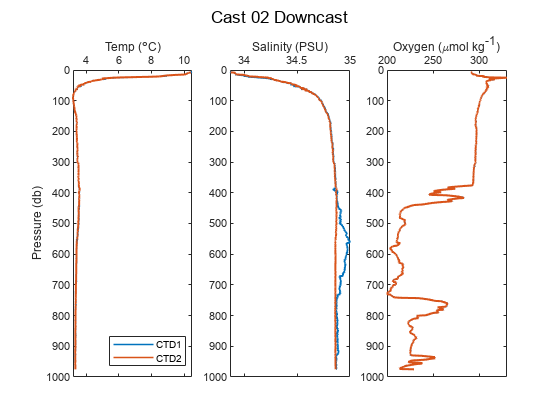

DO1 - DO2 = 0.047268 +/- 0.012784 umol/kg


[DOdiff02d, DOstd02] = CTD1vsCTD2(cast02dCTD1,cast02dCTD2,btlsum02CTD1,'Cast 02 Downcast');

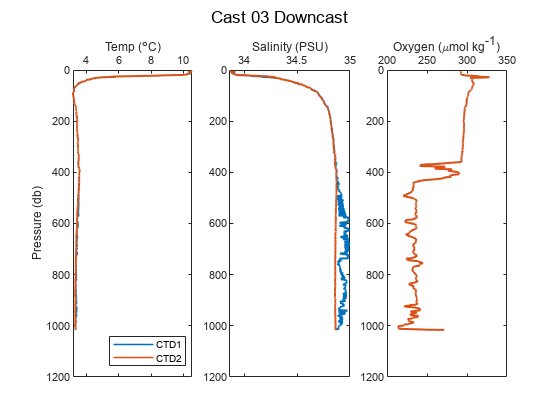

DO1 - DO2 = 0.045352 +/- 0.013168 umol/kg


[DOdiff03d, DOstd03] = CTD1vsCTD2(cast03dCTD1,cast03dCTD2,btlsum03CTD1,'Cast 03 Downcast');

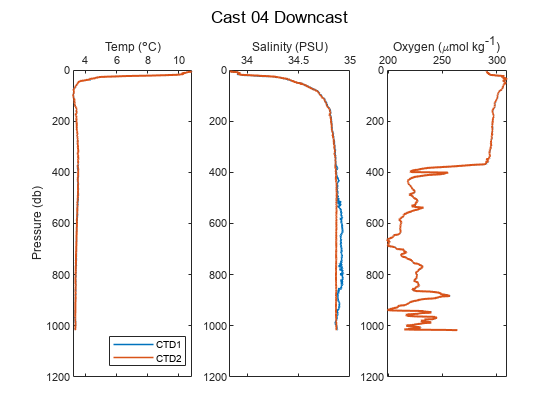

DO1 - DO2 = 0.047099 +/- 0.010728 umol/kg


[DOdiff04d, DOstd04] = CTD1vsCTD2(cast04dCTD1,cast04dCTD2,btlsum04CTD1,'Cast 04 Downcast');

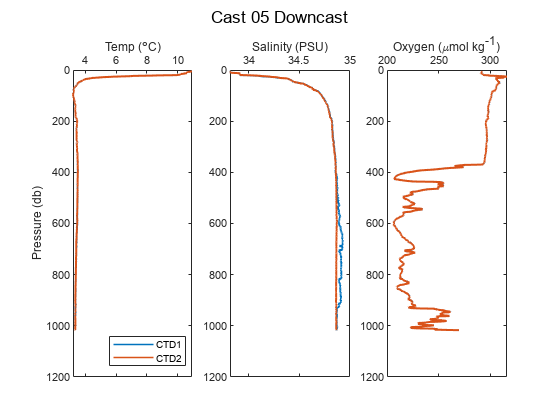

DO1 - DO2 = 0.047845 +/- 0.010418 umol/kg


[DOdiff05d, DOstd05] = CTD1vsCTD2(cast05dCTD1,cast05dCTD2,btlsum05CTD1,'Cast 05 Downcast');

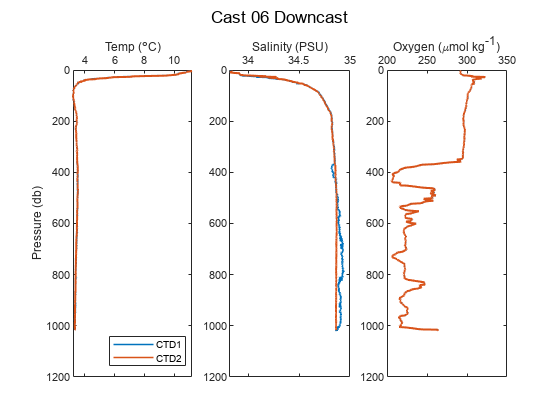

DO1 - DO2 = 0.047971 +/- 0.010937 umol/kg


[DOdiff06d, DOstd06] = CTD1vsCTD2(cast06dCTD1,cast06dCTD2,btlsum06CTD1,'Cast 06 Downcast');

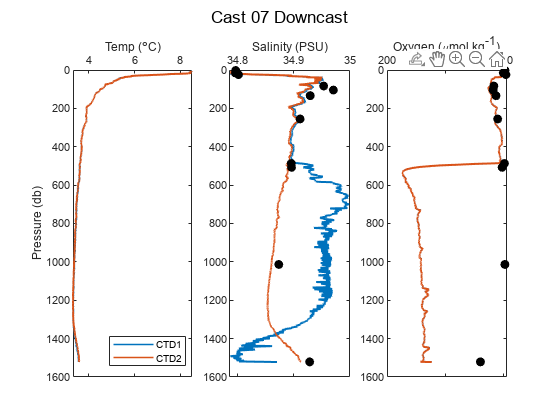

DO1 - DO2 = 0.042674 +/- 0.014569 umol/kg


[DOdiff07d, DOstd07] = CTD1vsCTD2(cast07dCTD1,cast07dCTD2,btlsum07CTD1,'Cast 07 Downcast');

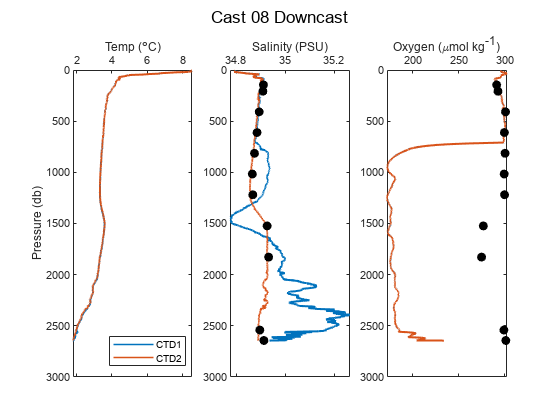

DO1 - DO2 = 0.034785 +/- 0.019956 umol/kg


[DOdiff08d, DOstd08] = CTD1vsCTD2(cast08dCTD1,cast08dCTD2,btlsum08CTD1,'Cast 08 Downcast');

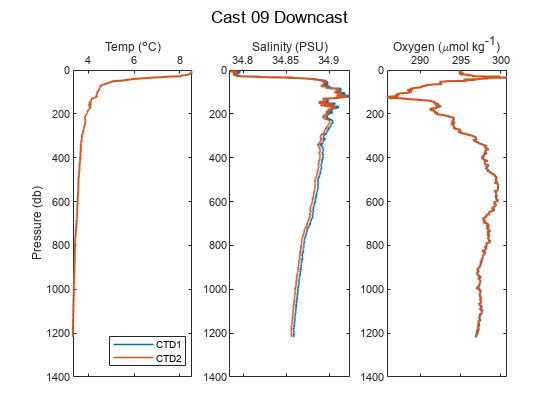

DO1 - DO2 = 0.059602 +/- 0.00065139 umol/kg


[DOdiff09d, DOstd09] = CTD1vsCTD2(cast09dCTD1,cast09dCTD2,btlsum09CTD1,'Cast 09 Downcast');

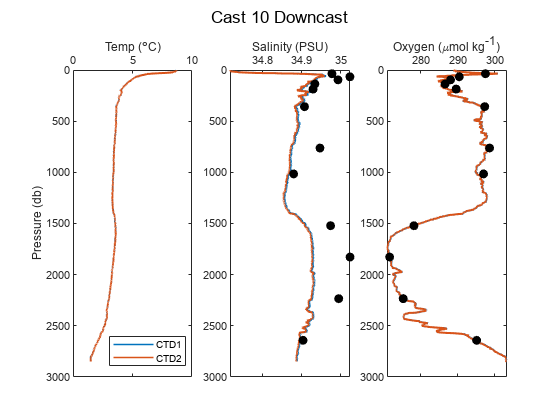

DO1 - DO2 = 0.057763 +/- 0.0020678 umol/kg


[DOdiff10d, DOstd10] = CTD1vsCTD2(cast10dCTD1,cast10dCTD2,btlsum10CTD1,'Cast 10 Downcast');

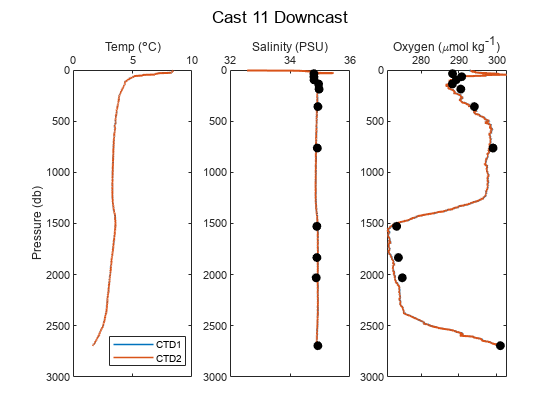

DO1 - DO2 = 0.057247 +/- 0.012056 umol/kg


[DOdiff11d, DOstd11] = CTD1vsCTD2(cast11dCTD1,cast11dCTD2,btlsum11CTD1,'Cast 11 Downcast');

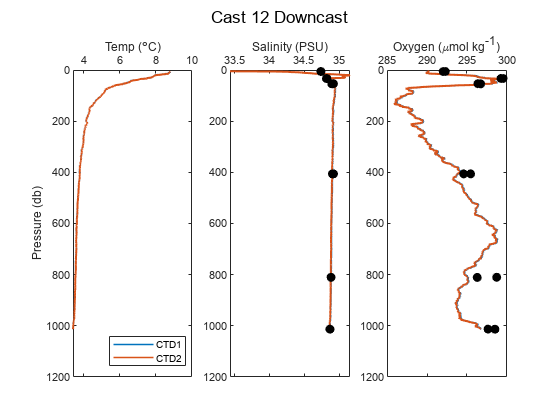

DO1 - DO2 = 0.058967 +/- 0.014037 umol/kg


[DOdiff12d, DOstd12] = CTD1vsCTD2(cast12dCTD1,cast12dCTD2,btlsum12CTD1,'Cast 12 Downcast');



DOdiff = [DOdiff01u DOdiff02u DOdiff03u DOdiff04u DOdiff05u DOdiff06u...
    DOdiff07u DOdiff08u DOdiff09u DOdiff10u DOdiff11u DOdiff12u...
    DOdiff01d DOdiff02d DOdiff03d DOdiff04d DOdiff05d DOdiff06d...
    DOdiff07d DOdiff08d DOdiff09d DOdiff10d DOdiff11d DOdiff12d];
nanmean(abs(DOdiff))

ans = 0.0528

nanstd(DOdiff)

ans = 0.0063

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
% dt_Processed = datetime;
% save Year4_CTD1vsCTD2_KF cast* dt_Processed 

function [DOdiff, DOstd] = CTD1vsCTD2(castCTD1,castCTD2,btlsumCTD,CastString)

    figure
    subplot(1,3,1)
    plot(castCTD1.temp1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.temp2,castCTD2.prs,'Linewidth',1.2)
    axis ij
    ylabel('Pressure (db)')
    xlabel('Temp (\circC)')
    ax = gca;
    ax.XAxisLocation = 'top';
    legend('CTD1','CTD2','Location','SE')

    subplot(1,3,2)
    plot(castCTD1.sal1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.sal2,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Discrete_Salinity_psu,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Salinity (PSU)')
    ax = gca;
    ax.XAxisLocation = 'top';
    
    subplot(1,3,3)
    plot(castCTD1.DOcorr_umolkg,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.DOcorr_umolkg,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Winkler_umolkg,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Oxygen (\mumol kg^-^1)')
    ax = gca;
    ax.XAxisLocation = 'top';
    sgtitle(CastString)

    DOdiff = nanmean(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg);
    DOstd = nanstd(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg);
    disp(['DO1 - DO2 = ' num2str(DOdiff) ' +/- ' num2str(DOstd) ' umol/kg'])

end